clear
clc
close all

fs     = 48e3;                                    % Sampling frequency
freq=18e3;
totalTime=20;
totalPoint=fs*totalTime;
t=(0:totalPoint-1)/fs;
audioData=cos(2*pi*freq*t);

freq=2e3;
totalTime=1;
totalPoint=fs*totalTime;
t=(0:totalPoint-1)/fs;
beep=0.01*cos(2*pi*freq*t);

N_seg  = 8192;                               % Chirp length
f0     = 17e3;                              % Starting frequency
f1     = 22e3;                              % Ending frequency
t_seg  = (0:N_seg-1) / fs;                  % Time series

flag = chirp(t_seg, f0, t_seg(end), f1).*hanning(N_seg)';  % Chirp signal

play_data= [audioData(1:fs*2),zeros(1,fs),flag,zeros(1,fs),beep,zeros(1,fs),audioData,zeros(1,fs*2),beep];

audiowrite('cw_18kHz_syn.wav',play_data,fs)

raw=pcmread_stereo('./data/yzq_wrist_20230924224918_mark.pcm')/2^15;
up_mic=raw(:,1);

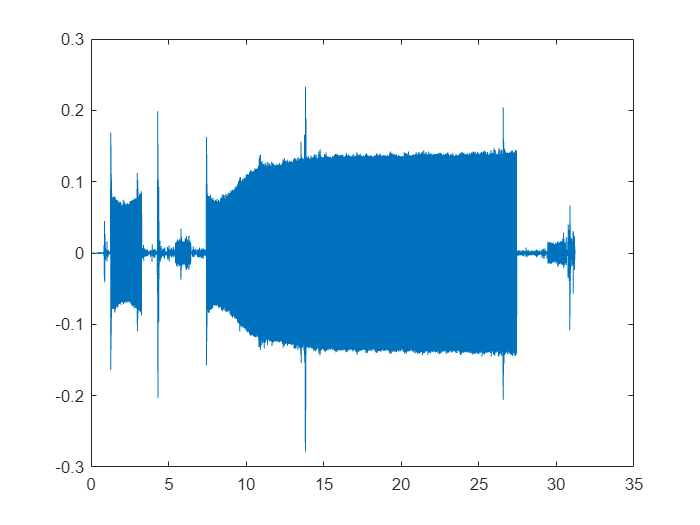

figure
plot( (1:length(up_mic))./fs ,up_mic)

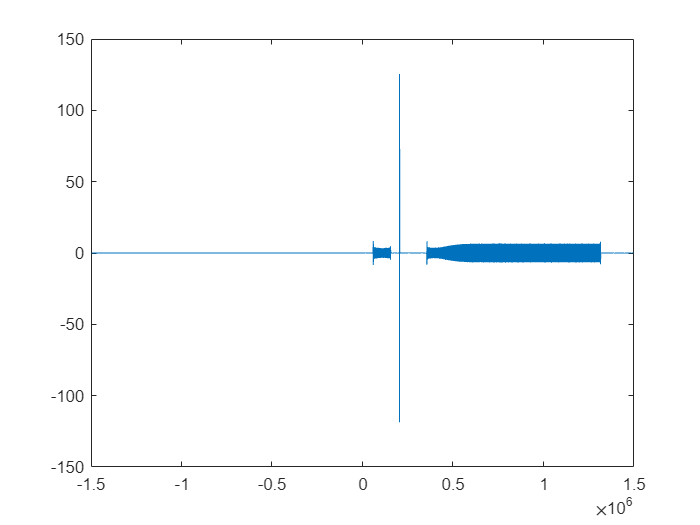

[f, l] = xcorr(up_mic, flag); % Cross-correlation
figure
plot(l,f)

idx=l(f == max(f));

with_pw=up_mic(idx+length(flag)+2*fs+length(beep):idx+length(flag)+2*fs+length(beep)+20*fs-1);

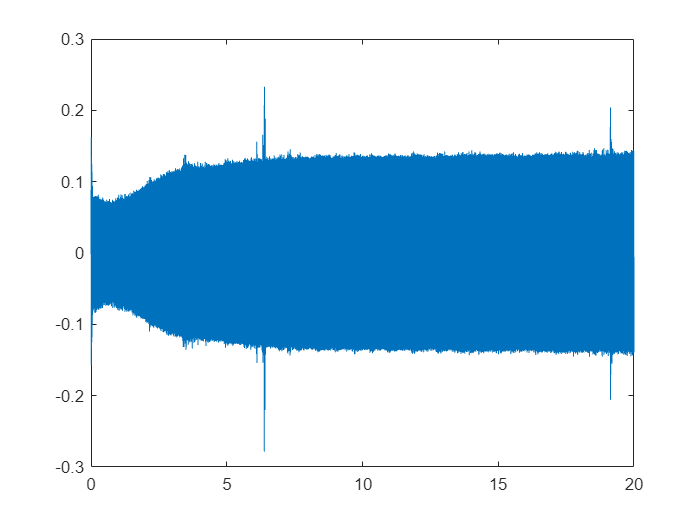

figure
plot((0 : 20*fs - 1)/fs ,with_pw)

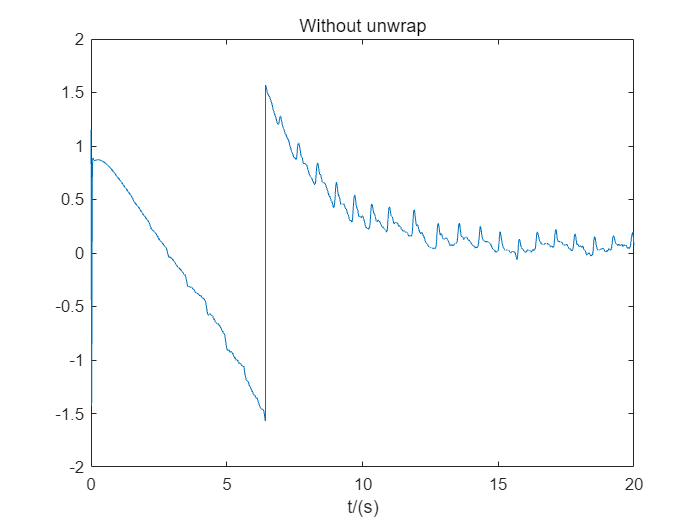

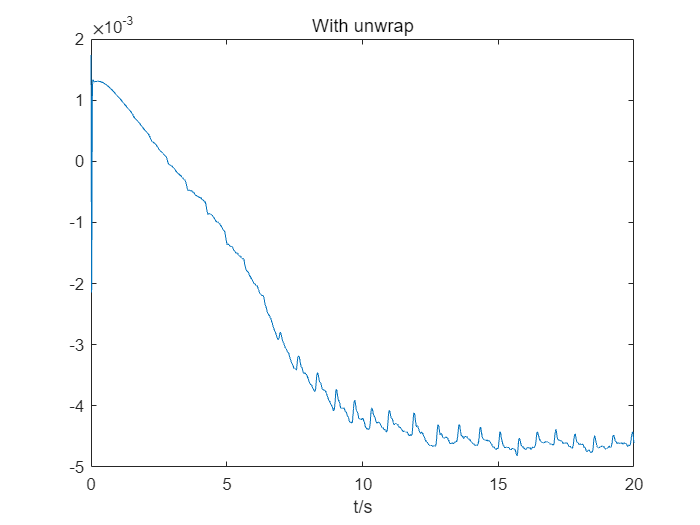

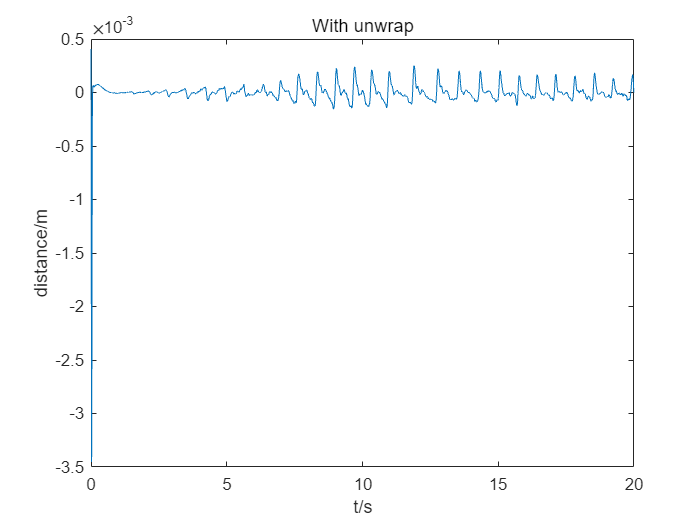

IQ_phase(18e3,with_pw);